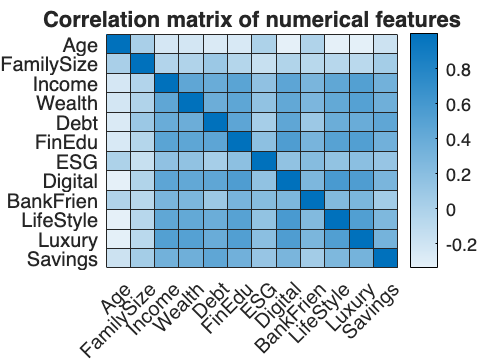

close all
clc
path = '/Users/Lorenzo/Desktop/Tesi/PossibiliDataset/BankClients.mat';

load BankClients.mat

% Numerical
N = vartype('numeric');
Data = BankClients(:,2:end); % Exclude 1st col = ID
% Removing the gender and the family size
%Data(:, "Gender") = [];
%Data(:, "FamilySize") = [];
NumFeatures = Data(:,N); % subtable of numerical features
XNum = NumFeatures.Variables; % create a matrix 
XNum = rescale(XNum); % normalize in [0, 1]
% Categorical
C = vartype('categorical');
CatFeatures = Data(:,C); % subtable of categorical features
% Encoding (ie create dummy variables)
%grp2idx create a vector of integer values from 1 up to the number K of distinct groups.
XCat = [];
for i = 1:size(CatFeatures, 2)
    XCat_i = dummyvar(grp2idx(CatFeatures{:,i}));
    XCat = [XCat XCat_i(:,1:end-1)]; % To use the dummy variables in a model, we must delete a column
end

X = [XCat XNum];

dati = Data;

figure
R = corrcoef(XNum); %computation of the correlation matric
yvalues = {'Age','FamilySize','Income','Wealth','Debt','FinEdu','ESG','Digital','BankFrien','LifeStyle','Luxury','Savings'};
xvalues = {'Age','FamilySize','Income','Wealth','Debt','FinEdu','ESG','Digital','BankFrien','LifeStyle','Luxury','Savings'};
h = heatmap(xvalues,yvalues, R );
h.Title = 'Correlation matrix of numerical features';

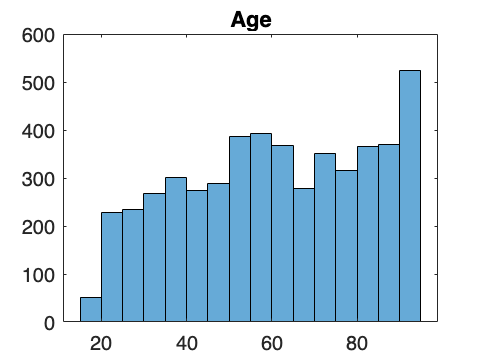


histogram(Data.Age)
title('Age')

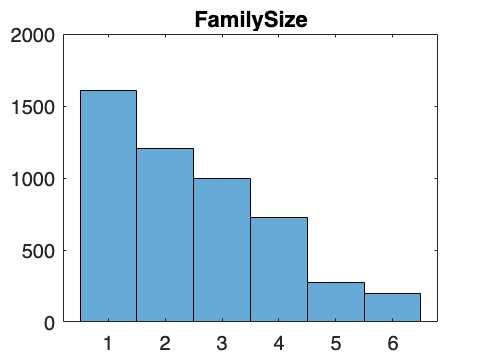


histogram(Data.FamilySize)
title('FamilySize')

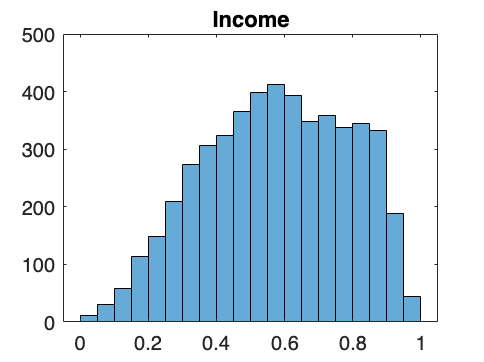


histogram(Data.Income)
title("Income")

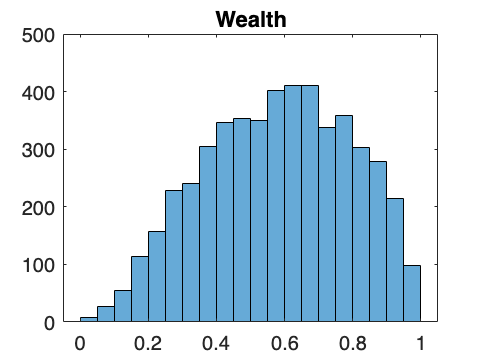


histogram(Data.Wealth)
title("Wealth")

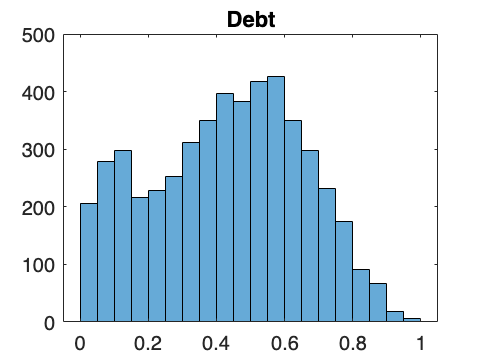


histogram(Data.Debt)
title("Debt")

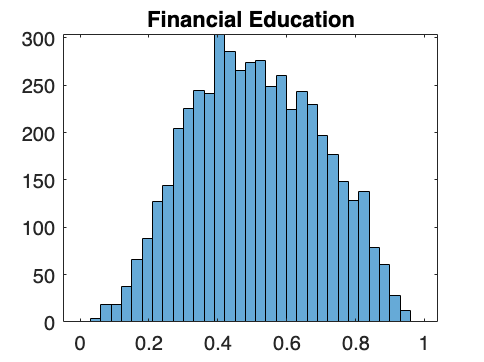


histogram(Data.FinEdu)
title("Financial Education")

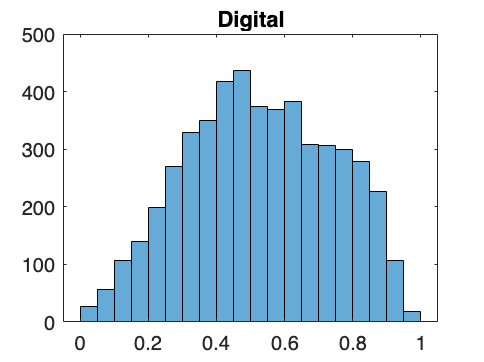


histogram(Data.Digital)
title("Digital")

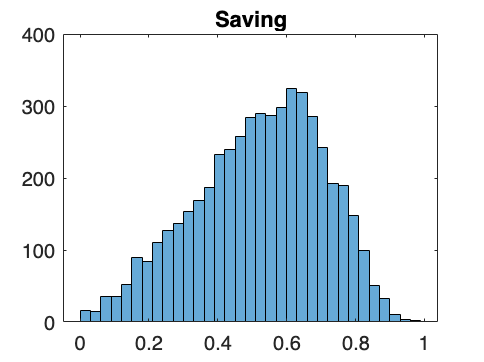


histogram(Data.Saving)
title('Saving')


tabulate(Data.Investments)

  Value    Count   Percent
      1     1314     26.28%
      2     1496     29.92%
      3     2190     43.80%



tabulate(Data.Job)

  Value    Count   Percent
      1      609     12.18%
      2     3284     65.68%
      3      144      2.88%
      4      107      2.14%
      5      856     17.12%


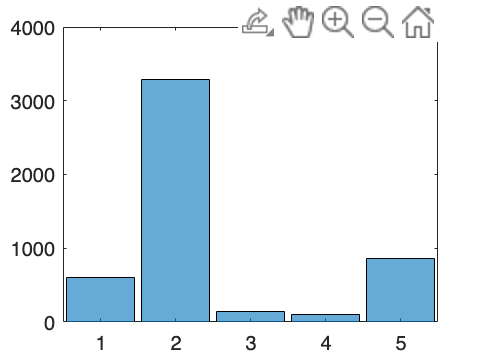


nSubSample = 1950;
rng('default') % for reproducibility
randRows = randperm(size(X, 1), nSubSample);
X = X(randRows', :);
%Dataset used later for cluster inspection
dati = dati(randRows', :); 


histogram(CatFeatures.Job)

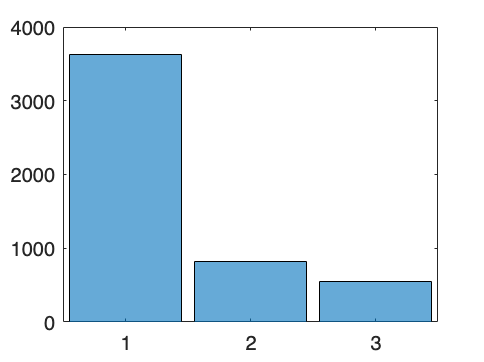


histogram(CatFeatures.Area)

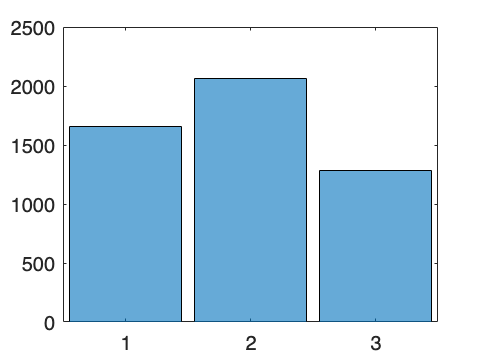


histogram(CatFeatures.CitySize)

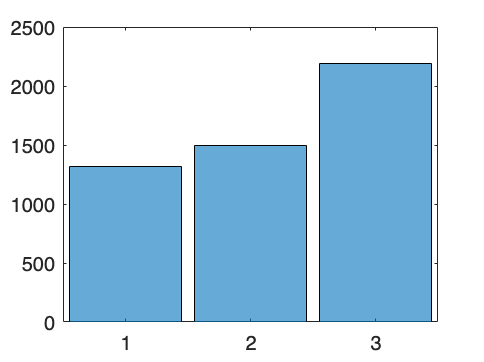


histogram(CatFeatures.Investments)

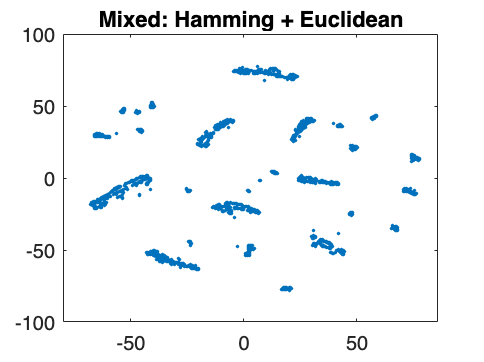




rng('default') % for reproducibility 9clu
Y = tsne(X,'Algorithm','exact','Distance', @MixDistance);
gscatter(Y(:,1),Y(:,2))
title('Mixed: Hamming + Euclidean')

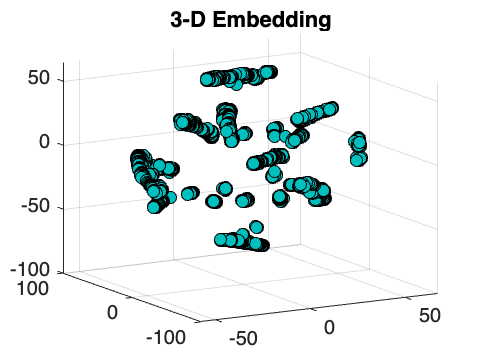


rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance', @MixDistance,'NumDimensions',3);
figure
scatter3(Y(:,1),Y(:,2),Y(:,3),...
        'MarkerEdgeColor','k',...
        'MarkerFaceColor',[0 .75 .75])
title('3-D Embedding')
view(-30,15)

D1 = pdist(X, @MixDistanceL1);   
%calculate the distance between every pair of objects in the dataset using MixDistanceL1
D2 = pdist(X, @MixDistanceL2); 
%calculate the distance between every pair of objects in the dataset using MixDistanceL2

%linkages using the L1 mix distance
single1 = linkage(D1, "single");
complete1 = linkage(D1, "complete");
average1 = linkage(D1, "average");
weighted1 = linkage(D1, "weighted");
%linkages using the L2 mix distance
single2 = linkage(D2, "single");
complete2 = linkage(D2, "complete");
average2 = linkage(D2, "average");
weighted2 = linkage(D2, "weighted");

c_single1 = cophenet(single1,D1)

c_single1 = 0.4840


c_single2 = cophenet(single2,D2)

c_single2 = 0.6539


c_average1 = cophenet(average1,D1)

c_average1 = 0.7188


c_average2 = cophenet(average2,D2)   % migliore, 0.8090

c_average2 = 0.8090


c_complete1 = cophenet(complete1,D1)

c_complete1 = 0.6140


c_complete2 = cophenet(complete2,D2)

c_complete2 = 0.7362


c_weighted1 = cophenet(weighted1,D1)

c_weighted1 = 0.6783


c_weighted2 = cophenet(weighted2,D2)

c_weighted2 = 0.7851

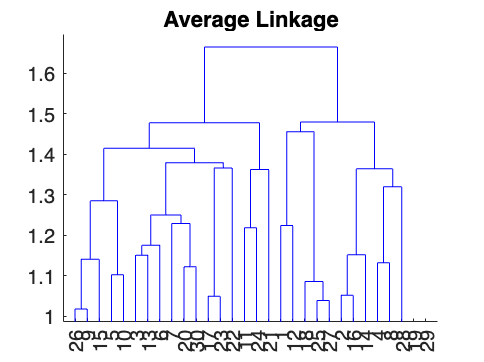

% Complete Dataset used for clustering
X = [XCat XNum];
% Dataset with the original variables used for cluster inspection
dati = Data;

D2 = pdist(X, @MixDistanceL2);
average2 = linkage(D2, "average");

figure
dendrogram(average2)
title("Average Linkage")

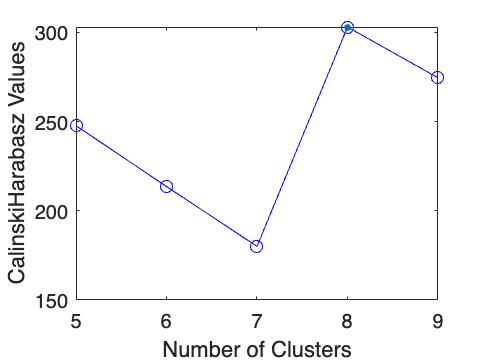

T5 = cluster(complete2,'maxclust',5);

T6 = cluster(complete2,'maxclust',6);

T7 = cluster(complete2,'maxclust',7);

T8 = cluster(complete2,'maxclust',8);

T9 = cluster(complete2,'maxclust',9);

clust = [T5 T6 T7 T8 T9];
eva1 = evalclusters(X,clust,'CalinskiHarabasz');
figure
plot(eva1)


eva1

eva1 =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 5000
         InspectedK: [5 6 7 8 9]
    CriterionValues: [247.6626 213.5695 180.0351 302.9430 274.4752]
           OptimalK: 8


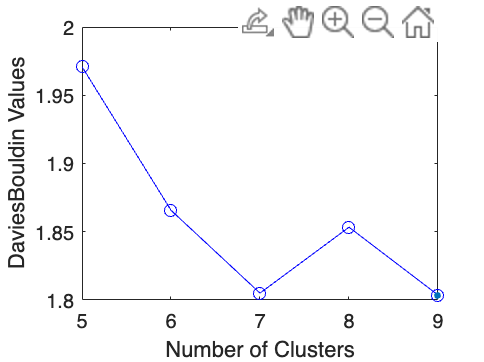


eva2 = evalclusters(X,clust,'DaviesBouldin');
figure
plot(eva2)


eva2

eva2 =   DaviesBouldinEvaluation with properties:

    NumObservations: 5000
         InspectedK: [5 6 7 8 9]
    CriterionValues: [1.9709 1.8657 1.8050 1.8533 1.8036]
           OptimalK: 9


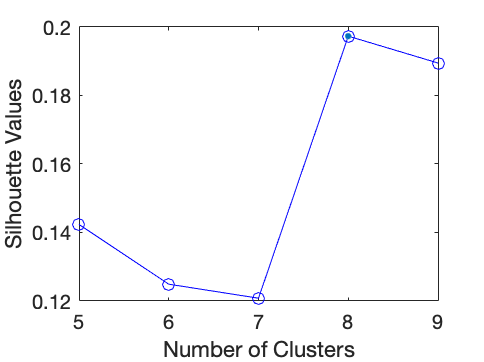


eva3 = evalclusters(X,clust,'silhouette');
figure
plot(eva3)


eva3

eva3 =   SilhouetteEvaluation with properties:

    NumObservations: 5000
         InspectedK: [5 6 7 8 9]
    CriterionValues: [0.1423 0.1249 0.1208 0.1973 0.1895]
           OptimalK: 8



tabulate(T9)

  Value    Count   Percent
      1       53      1.06%
      2     3965     79.30%
      3      554     11.08%
      4      422      8.44%
      5        3      0.06%
      6        3      0.06%



tabulate(T5)

  Value    Count   Percent
      1      554     11.08%
      2      422      8.44%
      3     4018     80.36%
      4        3      0.06%
      5        3      0.06%



tabulate(T6)

  Value    Count   Percent
      1       53      1.06%
      2     3965     79.30%
      3      554     11.08%
      4      422      8.44%
      5        3      0.06%
      6        3      0.06%



tabulate(T7)

  Value    Count   Percent
      1        8      0.16%
      2      414      8.28%
      3       53      1.06%
      4     3965     79.30%
      5      554     11.08%
      6        3      0.06%
      7        3      0.06%



tabulate(T8)

  Value    Count   Percent
      1     1639     32.78%
      2     2326     46.52%
      3        8      0.16%
      4      414      8.28%
      5       53      1.06%
      6      554     11.08%
      7        3      0.06%
      8        3      0.06%



tabulate(T9)

  Value    Count   Percent
      1     2285     45.70%
      2       41      0.82%
      3     1639     32.78%
      4        8      0.16%
      5      414      8.28%
      6       53      1.06%
      7      554     11.08%
      8        3      0.06%
      9        3      0.06%


% Select the number of the cluster
Z = dati(T6==6,:);

% Frequency tables
tabulate(Z.Job)

  Value    Count   Percent
      1        2     66.67%
      2        0      0.00%
      3        0      0.00%
      4        0      0.00%
      5        1     33.33%


tabulate(Z.Area)

  Value    Count   Percent
      1        0      0.00%
      2        0      0.00%
      3        3    100.00%


tabulate(Z.CitySize)

  Value    Count   Percent
      1        0      0.00%
      2        0      0.00%
      3        3    100.00%


tabulate(Z.Investments)

  Value    Count   Percent
      1        0      0.00%
      2        0      0.00%
      3        3    100.00%



summary(Z(:,"Age"))

Variables:

    Age: 3×1 double

        Values:

            Min          63   
            Median       83   
            Max          89   



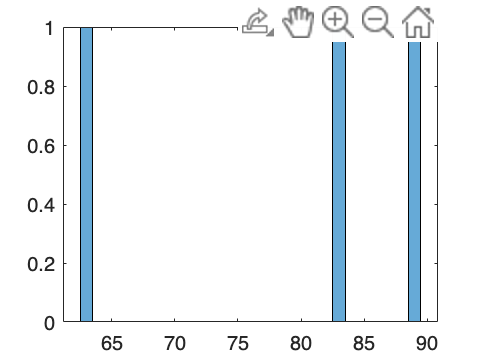

histogram(Z.Age)

mean(Z.Age)

ans = 78.3333


summary(Z(:, "Income"))

Variables:

    Income: 3×1 double

        Values:

            Min       0.47462 
            Median    0.48241 
            Max       0.51494 



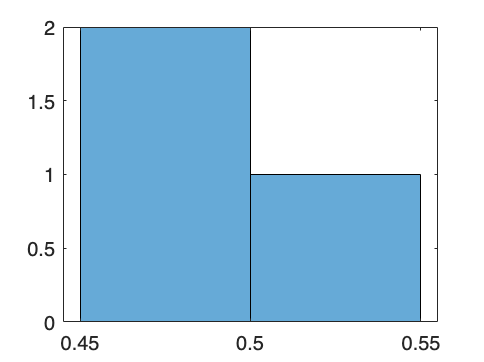

histogram(Z.Income)

mean(Z.Income)

ans = 0.4907


summary(Z(:, "Wealth"))

Variables:

    Wealth: 3×1 double

        Values:

            Min       0.43949 
            Median    0.60566 
            Max       0.72471 



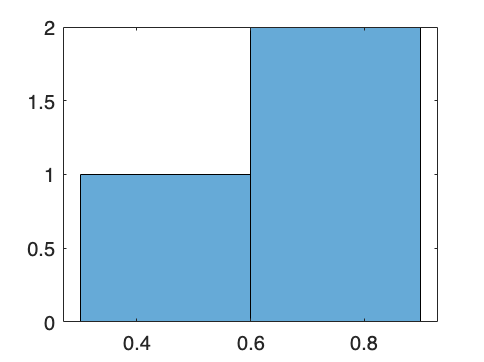

histogram(Z.Wealth)

mean(Z.Wealth)

ans = 0.5900


summary(Z(:, "Debt"))

Variables:

    Debt: 3×1 double

        Values:

            Min       0.43817 
            Median    0.51284 
            Max       0.53166 



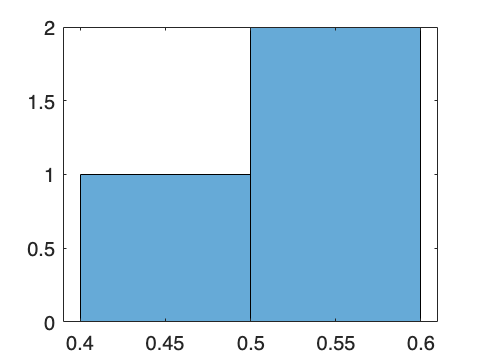

histogram(Z.Debt)

mean(Z.Debt)

ans = 0.4942


summary(Z(:, "FinEdu"))

Variables:

    FinEdu: 3×1 double

        Values:

            Min       0.48718 
            Median     0.5842 
            Max       0.73007 



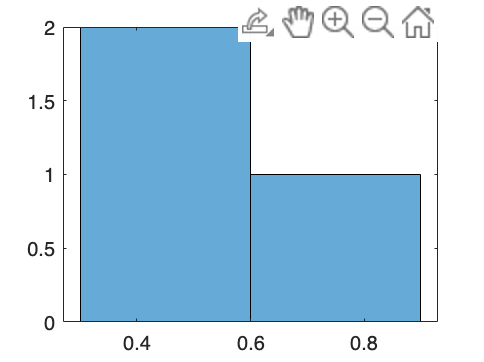

histogram(Z.FinEdu)

mean(Z.FinEdu)

ans = 0.6005


summary(Z(:, "ESG"))

Variables:

    ESG: 3×1 double

        Values:

            Min       0.29192 
            Median    0.40545 
            Max       0.44776 



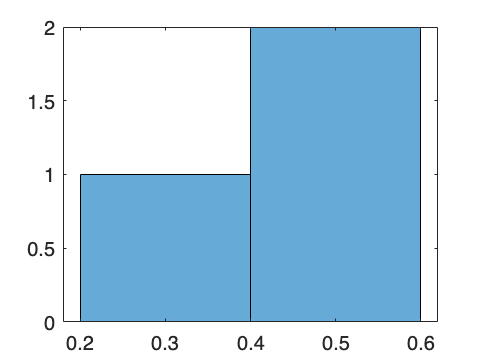

histogram(Z.ESG)

mean(Z.ESG)

ans = 0.3817


summary(Z(:, "Digital"))

Variables:

    Digital: 3×1 double

        Values:

            Min        0.4267 
            Median    0.57432 
            Max       0.60753 



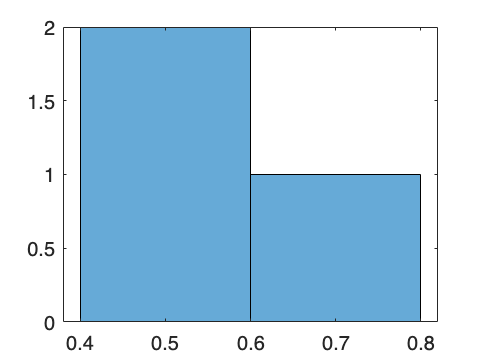

histogram(Z.Digital)

mean(Z.Digital)

ans = 0.5362


summary(Z(:, "BankFriend"))

Variables:

    BankFriend: 3×1 double

        Values:

            Min       0.61604 
            Median    0.69389 
            Max       0.81165 



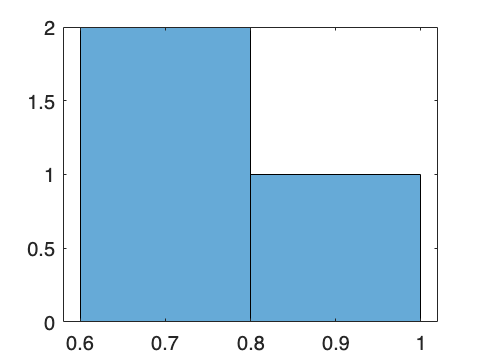

histogram(Z.BankFriend)

mean(Z.BankFriend)

ans = 0.7072


summary(Z(:, "LifeStyle"))

Variables:

    LifeStyle: 3×1 double

        Values:

            Min       0.41496 
            Median    0.63119 
            Max       0.70155 



histogram(Z.LifeStyle)

mean(Z.LifeStyle)

ans = 0.5826


summary(Z(:, "Luxury"))

Variables:

    Luxury: 3×1 double

        Values:

            Min       0.59365 
            Median    0.67143 
            Max        0.6971 



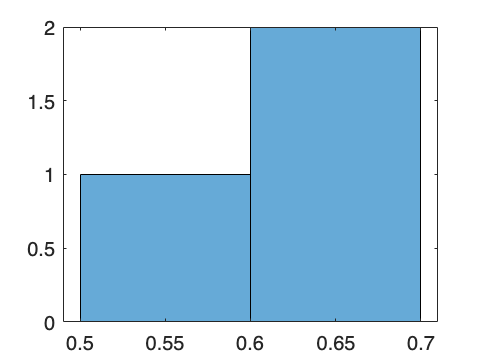

histogram(Z.Luxury)

mean(Z.Luxury)

ans = 0.6541


summary(Z(:, "Saving"))

Variables:

    Saving: 3×1 double

        Values:

            Min       0.37946 
            Median    0.45974 
            Max       0.69507 



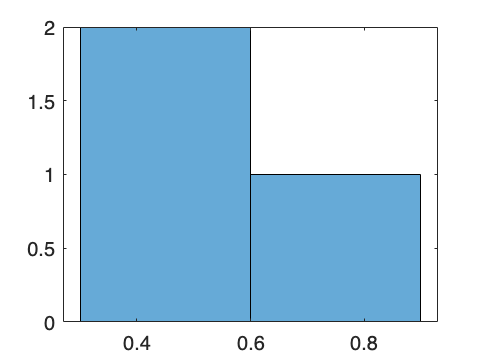

histogram(Z.Saving)

mean(Z.Saving)

ans = 0.5114


% Select the number of the cluster
Z = dati(T6==5,:);




% next step tirare fuori l'indice dei 6 negli ultimi due cluster
% provare ad escluderli e rivedere come clusterizza il resto dei dati
